# 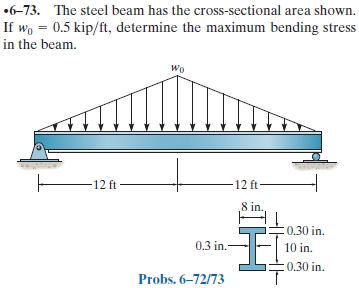

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-73P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-73P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

w1 = findpoly(1, 'thru', [0 0], 'thru', [12*u.ft -0.5*u.kip/u.ft]);
w2 = findpoly(1, 'thru', [12*u.ft -0.5*u.kip/u.ft], 'thru', [24*u.ft 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'R1', 0);
b = b.add('reaction', 'force', 'R2', 24*u.ft);
b = b.add('distributed', 'force', w1, [0 12*u.ft]);
b = b.add('distributed', 'force', w2, [12*u.ft 24*u.ft], [false true]);
b.L = 24*u.ft;

# section properties

yc = [10/2+0.30/2 0 -10/2-0.30/2]*u.in;
Ac = [8*0.30 0.30*10 8*0.30]*u.in^2;
Ic = [8*0.30^3 0.30*10^3 8*0.30^3]/sym(12)*u.in^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{900\,x\,{\left(720\,{\mathrm{ft}}^{2}-x^{2}\right)}^{2}}{19043\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{6}} & \text{ if }x\leq 12\,\mathrm{ft}\\ \frac{900\,\left(x-24\,\mathrm{ft}\right)\,{\left(-x^{2}+48\,x\,\mathrm{ft}+144\,{\mathrm{ft}}^{2}\right)}^{2}}{19043\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{6}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{4500\,\left(x-12\,\mathrm{ft}\right)\,\left(x+12\,\mathrm{ft}\right)\,\left(720\,{\mathrm{ft}}^{2}-x^{2}\right)}{19043\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{6}} & \text{ if }x\leq 12\,\mathrm{ft}\\ -\frac{4500\,\left(x-12\,\mathrm{ft}\right)\,\left(x-36\,\mathrm{ft}\right)\,\left(-x^{2}+48\,x\,\mathrm{ft}+144\,{\mathrm{ft}}^{2}\right)}{19043\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{6}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{x\,\left(432\,{\mathrm{ft}}^{2}-x^{2}\right)}{144}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 12\,\mathrm{ft}\\ \frac{\left(x-24\,\mathrm{ft}\right)\,\left(x^{2}-48\,x\,\mathrm{ft}+144\,{\mathrm{ft}}^{2}\right)}{144}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{\left(x-12\,\mathrm{ft}\right)\,\left(x+12\,\mathrm{ft}\right)}{48}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 12\,\mathrm{ft}\\ \frac{\left(x-12\,\mathrm{ft}\right)\,\left(x-36\,\mathrm{ft}\right)}{48}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{x}{24}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 12\,\mathrm{ft}\\ \frac{x-24\,\mathrm{ft}}{24}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} R_{1} & 3\,\mathrm{kip}\\ R_{2} & 3\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

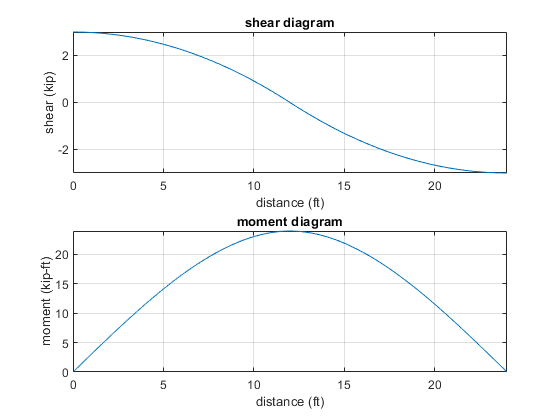

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# maximum bending stress

M_max = m(12*u.ft)

$$M\_max = 24\,\mathrm{ft}\,\mathrm{kip}$$

C = (5+0.30)*u.in;
b.I = rewrite(b.I, u.in);
sigma_max = rewrite(M_max*C/b.I, u.ksi);
sigma_max_vpa = vpa(sigma_max, 4) %#ok<NASGU> 

$$sigma\_max\_vpa = 10.02\,\mathrm{ksi}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear sigma_max_vpa;